% E9.7
clear all
syms s K

% Ls의 pole을 구하는 과정.
Ls = K/(s-5);
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 5 (Ls의 양수부 pole은 1개이다.)

$$s = 5$$


s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성



sys_leg1 = []


sys_leg1 =

     []



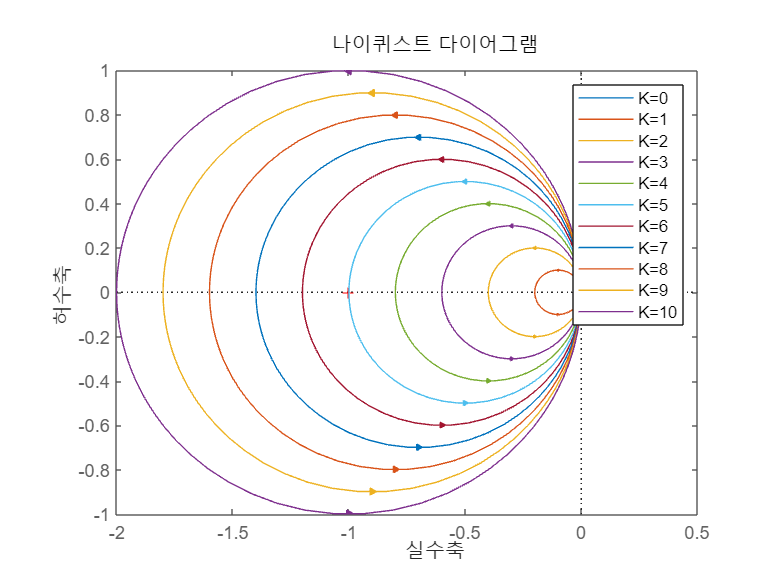

for K = 0:10
    Ls = K/(s-5);
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end
legend(sys_leg1);
hold off

% K=5 일 때는 nyquist 선도가 (-1,0)을 지나며,
% K>5 일 때는 nyquist 선도가 (-1,0)을 반시계 방향으로 1번 둘러싸고,
% K<5 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싼다.
% 
% Ls의 양수부 pole이 1개이므로, 시스템이 안정적이기 위해서는 
% nyquist 선도가 (-1,0)을 반시계 방향으로1번 둘러싸야 한다.
% 따라서 K>5 일 때 시스템은 안정하다